load mtlb

% change sampling rate of mtlb
fs = 48000;
[P,Q] = rat(fs/Fs);

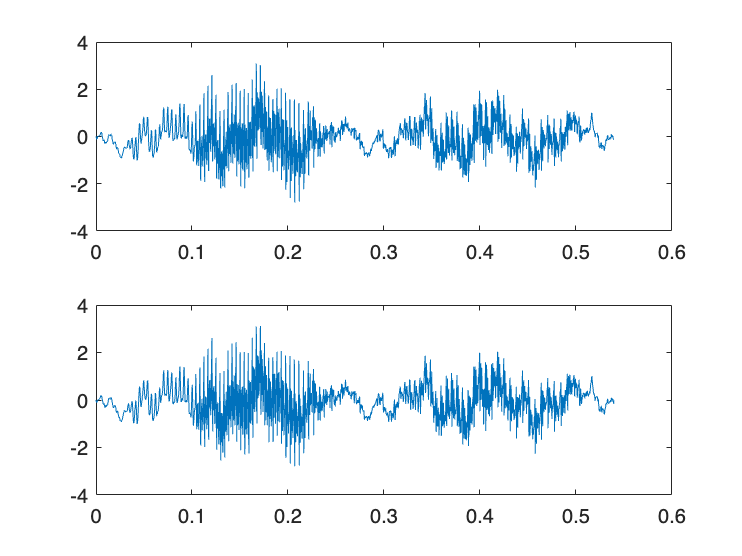

mtlb_new = resample(mtlb,P,Q);

subplot(2,1,1)
plot((0:length(mtlb)-1)/Fs,mtlb)
subplot(2,1,2)
plot((0:length(mtlb_new)-1)/(P/Q*Fs),mtlb_new)

% alpha: y(n)=x(n)+alpha*x(n−delta)
timelag = 0.23;
delta = round(fs*timelag);
alpha = 0.5;

orig = [mtlb_new;zeros(delta,1)];
echo = [zeros(delta,1);mtlb_new]*alpha;

mtEcho = orig + echo;

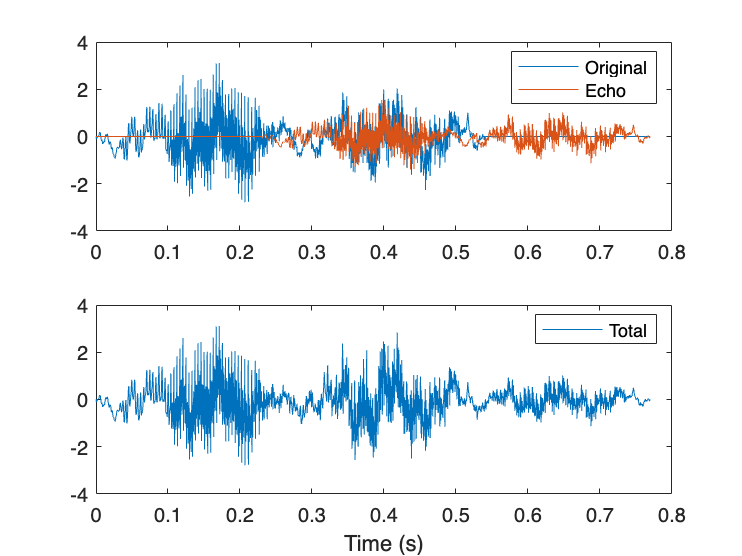

t = (0:length(mtEcho)-1)/fs;

subplot(2,1,1)
plot(t,[orig echo])
legend('Original','Echo')

subplot(2,1,2)
plot(t,mtEcho)
legend('Total')
xlabel('Time (s)')

% uncomment to hear echo
soundsc(mtEcho,fs)

% generate wav file of echo


% fileName = "echo_file1"
% 
% audiowrite(char(fileName + ".wav"), mtEcho, fs)
% 
% if ismac
%     cmd = "afconvert -f caff -d LEI16@" + num2str(fs) + " -c 1 " + fileName + ".wav " + fileName + ".caf"
% end
% 
% system(cmd)

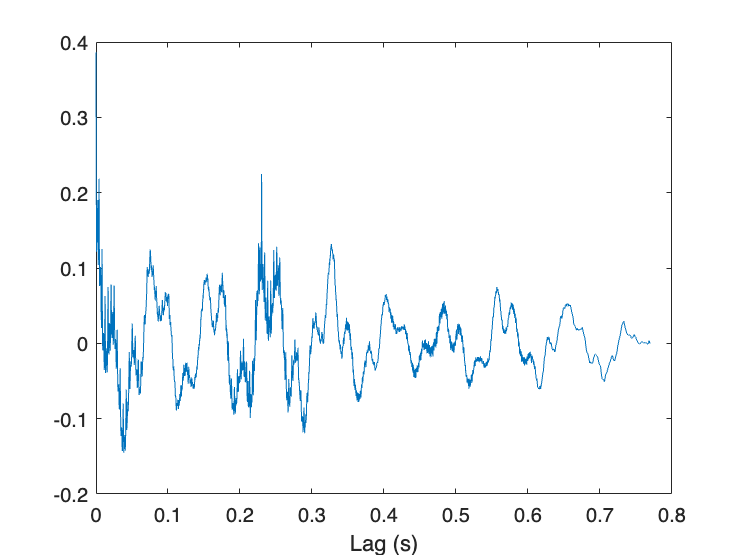

[Rmm,lags] = xcorr(mtEcho,'unbiased');

Rmm = Rmm(lags>0);
lags = lags(lags>0);

figure
plot(lags/fs,Rmm)
xlabel('Lag (s)')

[~,dl] = findpeaks(Rmm,lags,'MinPeakHeight',0.22);

mtNew = filter(1,[1 zeros(1,dl-1) alpha],mtEcho);

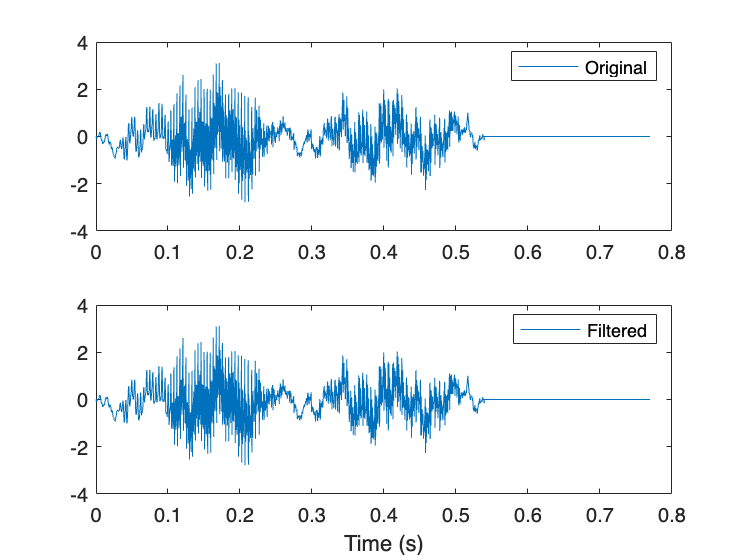

subplot(2,1,1)
plot(t,orig)
legend('Original')

subplot(2,1,2)
plot(t,mtNew)
legend('Filtered')
xlabel('Time (s)')

% To hear new w/o echo, uncomments
soundsc(mtNew,fs)